clear;clc;close all
layerfolder='../data/Capas_SouthAmerica_5M/';%Route to folder with ambiental data
Dimensions = ReadLayers(layerfolder); %The 19 environmental variables for all the map

----Reading layers----
Elapsed time is 11.666921 seconds.


Elapsed time is 16.274776 seconds.


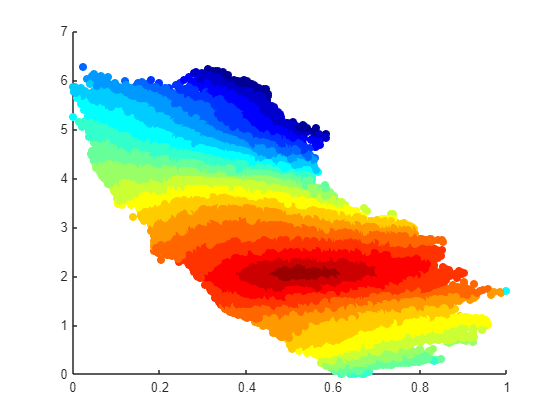

Elapsed time is 16.595114 seconds.


InfoInitialPoint = InitialPoint(Dimensions, 'harmonic'); %Generate a initial point to generate a niche

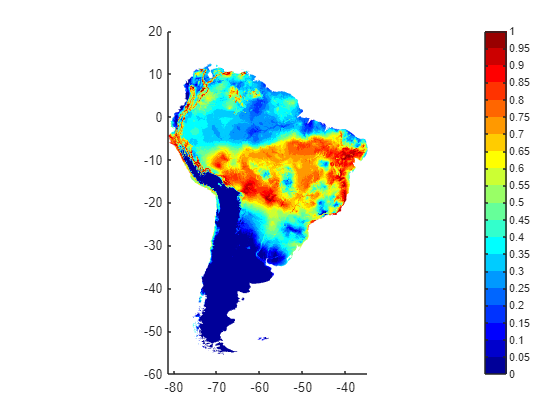

MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.8, true); %Generate the niche based on the initial point

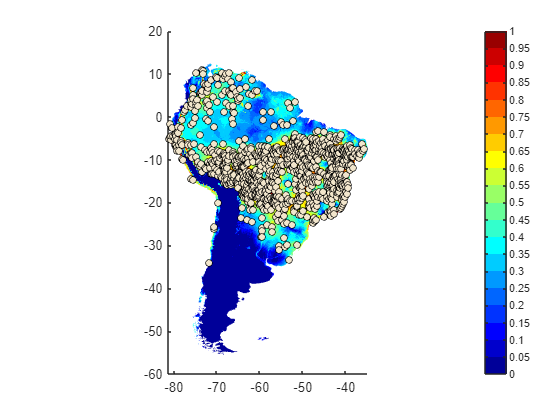

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 1000, -3, true, 'GenSP', true, true); %Generate samples based on the generated niche

close all, clf
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers

%ColoringBorder generates classifier object with atributes nodes = environmental variables
%for each frontier point, 
%T = table with samples and information
%readInfo = dimensions of the map
%alpha = shrinking factor

classA1 = ColoringBorder(T,Dimensions,1,false,outlier,outlier2); 

MapMetric(MapInfo.Map,classA1.map,false)

ans =     0.9482    0.7901


%T = table with samples and information
%readInfo = dimensions of the map
%percentile = percentile with which the radius will be taken
%alpha = shrinking factor

classB1 = ColoringRadius(T,Dimensions,1,25,show,outlier,outlier2); 

classB2 = ColoringRadiusPercentile(T,Dimensions,1,25,true,false,false); 

MapMetric(MapInfo.Map,classA1.map,false) %accuracy of the generated colored map compared to the the original niche

ans =     0.7666    0.8283


MapMetric(MapInfo.Map,classB1.map,false) 

ans =     0.8907    0.9275


MapMetric(MapInfo.Map,classB2.map,false)

ans =     0.9111    0.9047


classA2 = ColoringWeightedBorder(T,Dimensions,1,show,outlier,outlier2);


[F,t] = ecdf(classA1.radius);
plot(t,1-F)
xlabel('X'); ylabel('F(x)')
title('Niche Probability Intensity Based on distance')